**The numeric simulations where all the protein degradation rate of proteins alpha=0**

**For Figure 1b.**

%%%initialization
rng('shuffle');
total=1e4;
muphi=zeros(total,6);


N=4e3;
mR=1.4e6;%Da

CV_keff=1.97;
mean_keff=48000;%Da/min
sigma_knorm=sqrt(log(1+CV_keff^2));
mean_knorm=log(mean_keff)-sigma_knorm^2/2;
k_norm=mean_knorm+sigma_knorm*randn(N-1,1);
keff_oth=exp(k_norm);
keff_R=20700;%Da/min
keff=[keff_R;keff_oth];


CV_alpha=1.755436;
mean_alpha=1.1e-3;%min-1
sigma_anorm=sqrt(log(1+CV_alpha^2));
mean_anorm=log(mean_alpha)-sigma_anorm^2/2;
a_norm=mean_anorm+sigma_anorm*randn(N-1,1);
alpha_oth=exp(a_norm);
alphaR=4.83e-4;
alpha=[alphaR;alpha_oth];
alpha=zeros(N,1); %degradation rate alpha=0

phi0=0.08;
chiRmax=1;
dphi=1e-3;



%%%simulation   
count=1;
for series=1:total

    chiR=chiRmax*rand(1); 
    temp_i=1;
    while temp_i ~=0
    CV_chi=rand(1)+4.5;
    sigmay=sqrt(log(1+CV_chi^2));
    meany=log(1)-sigmay^2/2;       
    chi_oth=exp(meany+sigmay*randn(N-1,1));
    chi_oth=(1-chiR)*chi_oth/sum(chi_oth);
    temp3= var(chi_oth)^0.5/mean(chi_oth);
    if temp3<5.5&&temp3>4.5
        temp_i=0;
    end
    end
    
    rou=(rand(1)-0.5)*2;
    %the correlation ranges from -1 to 1
    u= copularnd('Gaussian',rou,N-1);
    [s1,i1] = sort(u(:,1));
    [s2,i2] = sort(u(:,2));
    keff_oth(i1) = sort(keff_oth);
    chi_oth(i2) = sort(chi_oth);
    
    chi=[chiR;chi_oth];
    keff=[keff_R;keff_oth];
    
    chi_oth3=chi_oth/(1-chiR);

   if min(chi_oth)<0
       continue
   end
    
    
    phi_min=phi0/(1-alpha(1)*mR/(keff_R*chi(1)));
    % the phR when mu=0
    
    if phi_min<0
    muphi(series,:)=[-1 -1 -1 -1 -1 -1];
    continue
    end
    
    phi_tot=(phi_min+dphi):dphi:1;
    phi_tot=sort(phi_tot,"descend");
    
    lphi=length(phi_tot);
    for i=1:lphi
        phiR=phi_tot(i);
      
        mu=keff_R*(1-phi0/phiR)*chi(1)/mR-alpha(1);
        fa=1-phi0/phiR;
       
        phiR_1=mR/(sum(keff.*chi*fa./(mu+alpha)));
       
        if phiR_1>=phiR
            break;
        end
        
    end
    %searching for the phR that makes muR=mu
   
    
    if isempty(i)
    muphi(series,:)=[-1 -1 -1 -1 -1 -1];
    continue
    end

    
    if i==lphi
    muphi(series,:)=[-1 -1 -1 -1 -1 -1];
    continue
    end
    if i==1
    muphi(series,:)=[-1 -1 -1 -1 -1 -1 ];
    continue
    end
    
       
    phi=keff.*chi*(phiR-phi0)./(mR*(alpha+mu));
    CV_phi=var(phi(2:N))^0.5/mean(phi(2:N));
    CV_chi=var(chi(2:N))^0.5/mean(chi(2:N));
    rou_pea_k=corr(chi(2:N),keff_oth,"type","Pearson");
    rou_pea_a=corr(phi(2:N),alpha_oth,"type","Pearson");
    
    Ik=rou_pea_k*CV_chi*CV_keff;
    Ia=rou_pea_a*CV_phi*CV_alpha;
    muphi(series,:)=[mu phiR Ik CV_phi Ia CV_chi];

end


pp=find(muphi(:,1)<0);
muphi(pp,:)=[];
pp=find(muphi(:,2)<0);
muphi(pp,:)=[];
pp=find(muphi(:,2)>=1);
muphi(pp,:)=[];



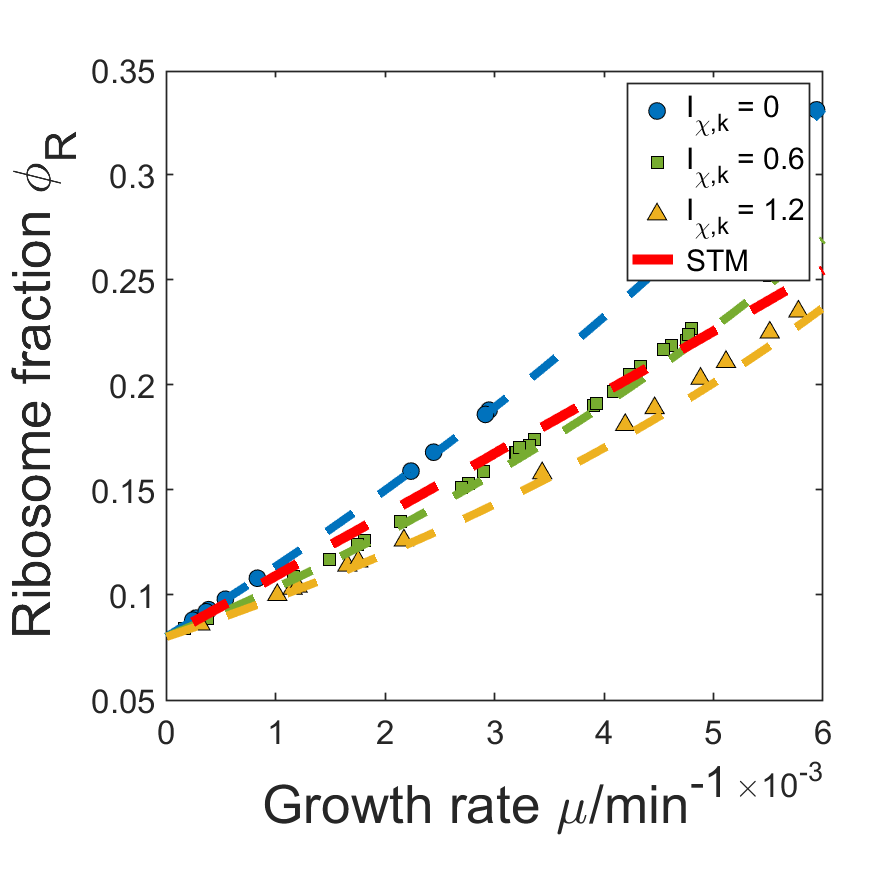

%%%plot
fig=figure;
set(fig,'Position',[300 100 700 700]);

ax1=axes('position', [0.19 0.2 0.75 0.72]);

muphi_cor=muphi;
pp=find(muphi_cor(:,3)>0.01);
muphi_cor(pp,:)=[];
pp=find(muphi_cor(:,3)<-0.01);
muphi_cor(pp,:)=[];
p3=plot(muphi_cor(:,1),muphi_cor(:,2),'o', ...
    'DisplayName','I_{\chi,k} = 0', ...
    "MarkerSize",10, ...
    'MarkerEdgeColor','black', ...
    'MarkerFaceColor',	'#0072BD');%,"Color",'#EDB120'
hold on;
muphi_cor=muphi;
pp=find(muphi_cor(:,3)>0.64);
muphi_cor(pp,:)=[];
pp=find(muphi_cor(:,3)<0.56);
muphi_cor(pp,:)=[];
p4=plot(muphi_cor(:,1),muphi_cor(:,2),'s', ...
    'DisplayName','I_{\chi,k} = 0.6', ...
    "MarkerSize",10, ...
    'MarkerEdgeColor','black', ...
    'MarkerFaceColor','#77AC30');%,"Color",'#7E2F8E'
hold on;
muphi_cor=muphi;
pp=find(muphi_cor(:,3)>1.22);
muphi_cor(pp,:)=[];
pp=find(muphi_cor(:,3)<1.18);
muphi_cor(pp,:)=[];
p5=plot(muphi_cor(:,1),muphi_cor(:,2),'^', ...
    'DisplayName','I_{\chi,k} = 1.2', ...
    "MarkerSize",10, ...
    'MarkerEdgeColor','black', ...
    'MarkerFaceColor','#EDB120');%,"Color",'#77AC30'
hold on;

%predication
rng('shuffle');
total=2e3;

var_chi=zeros(1,total);

i_0=0;
i_1=[0 0.6 1.2];
color_seq=[[0 0.4470 0.7410];[0.4660 0.6740 0.1880];[0.9290 0.6940 0.1250]];

for Ikx=i_1
i_0=i_0+1;

muphi_pre=Ik_fun(1000,Ikx,keff_R);


plot(muphi_pre(:,1),muphi_pre(:,2),'--',"LineWidth",5,'DisplayName','',"Color",color_seq(i_0,:)) 
hold on
end

%predication with STM
load muphi_stm.mat
p6=plot(muphi_stm(:,1),muphi_stm(:,2),'--',"LineWidth",6,'DisplayName','STM',"Color","red");

set(ax1,'LabelFontSizeMultiplier',1.2,'linewidth',1);
set(gca,'FontSize',20)
xlabel('Growth rate \mu/min^{-1}','interpreter','tex','FontSize',32);
ylabel('Ribosome fraction \phi_R','interpreter','tex','FontSize',32);
axis([0 6e-3,0.05 0.35])
box on

legend([p3 p4 p5 p6])
hold off

The prediction function.

function[muphi]=Ik_fun(total,Ikx,keff_R)

mR=1.4e6;

mean_keff=48000;


phi0=0.08;

muphi=zeros(total,6);

   phiR=0:1/(total-1):1;
   mu= - ((keff_R*phi0 - keff_R*phiR)*(mean_keff + Ikx*mean_keff))./(mR*(keff_R - keff_R*phiR + mean_keff*phiR + Ikx*mean_keff*phiR));
   
   muphi(:,1)=mu;
   muphi(:,2)=phiR;


pp=find(muphi(:,1)<=0);
muphi(pp,:)=[];

pp=find(muphi(:,2)<=0);
muphi(pp,:)=[];

pp=find(muphi(:,2)>1);
muphi(pp,:)=[];




end
